cd(fileparts(matlab.desktop.editor.getActiveFilename))
close all; clearvars; clc

cd("../data-engineering")
load("../../temp-data/participant_list.mat")
cd(fileparts(matlab.desktop.editor.getActiveFilename))

Compute TRMSE metric and make repeated measure tables.

metric_type = "lmaj";
metric_task = "none";
y = compute_performance_table(participant_array, metric_type, metric_task);

Participant 01: P05
	Condition: par
		Task: ml
			Trial 01	Co-Activation:6.283	 Differentiation:6.403
			Trial 02	Co-Activation:6.201	 Differentiation:6.128
			Trial 03	Co-Activation:5.974	 Differentiation:5.365
			Trial 04	Co-Activation:6.171	 Differentiation:6.397
			Trial 05	Co-Activation:6.103	 Differentiation:6.306
			Trial 06	Co-Activation:5.724	 Differentiation:6.215
			Trial 07	Co-Activation:6.113	 Differentiation:6.247
			Trial 08	Co-Activation:6.237	 Differentiation:6.306
			Trial 09	Co-Activation:6.236	 Differentiation:6.307
		Task: hl
			Trial 01	Co-Activation:6.822	 Differentiation:5.678
			Trial 02	Co-Activation:7.083	 Differentiation:6.748
			Trial 03	Co-Activation:6.895	 Differentiation:6.865
			Trial 04	Co-Activation:6.874	 Differentiation:6.809
			Trial 05	Co-Activation:6.917	 Differentiation:6.783
			Trial 06	Co-Activation:6.914	 Differentiation:6.775
			Trial 07	Co-Activation:6.838	 Differentiation:6.635
			Trial 08	Co-Activation:6.655	 Differentiation:6.415
			Tria

### Data Visualizer

y_between = y

y_between = 12×55 table
    b_condition     y_1       y_2       y_3       y_4       y_5       y_6       y_7       y_8       y_9       y_10      y_11      y_12      y_13      y_14      y_15      y_16      y_17      y_18      y_19      y_20      y_21      y_22      y_23      y_24      y_25      y_26      y_27      y_28      y_29      y_30      y_31      y_32      y_33      y_34      y_35

w_task = [repmat("Machine Learning", 18,1); repmat("Human Learning", 18,1); repmat("Co-Adaptive Learning", 18, 1)];
w_gesture = repmat([repmat("Co-Activation", 9,1); repmat("Differentiation", 9,1)], 3,1);
w_trial = repmat([1:9]', 6,1);
y_within = table(w_task, w_gesture, w_trial)

y_within = 54×3 table
          w_task              w_gesture        w_trial
    __________________    _________________    _______

    "Machine Learning"    "Co-Activation"         1   
    "Machine Learning"    "Co-Activation"         2   
    "Machine Learning"    "Co-Activation"         3   
    "Machine Learning"    "Co-Activation"         4   
    "Machine Learning"    "Co-Activation"         5   
    "Machine Learning"    "Co-Activation"         6   
    "Machine Learning"    "Co-Activation"         7   
    "Machine Learning"    "Co-Activation"         8   
    "Machine Learning"    "Co-Activation"         9   
    "Machine Learning"    "Differentiation"       1   
    "Machine Learning"    "Differentiation"       2   
    "Machine Learning"    "Differentiation"       3   
    "Machine Learning"    "Differentiation"       4   
    "Machine Learning"    "Differentiation"       

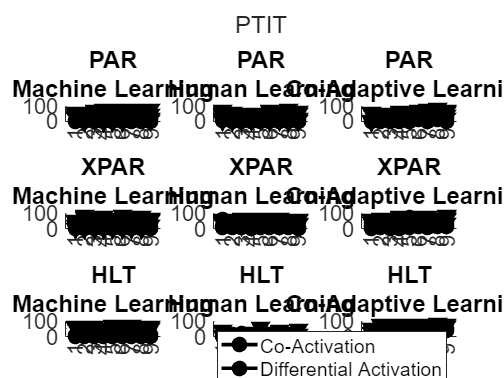

tlo = tiledlayout('flow');
fontsize(tlo, 20, "points")
ax_handle_list = [];
for cond = ["par", "xpar", "hlt"]
    y_cond = y_between(y_between.b_condition==cond,2:end);
    for task = ["Machine Learning", "Human Learning", "Co-Adaptive Learning"]
        y_coact = y_cond(:, and(y_within.w_task == task, y_within.w_gesture == "Co-Activation"));
        y_diffact = y_cond(:, and(y_within.w_task == task, y_within.w_gesture == "Differentiation"));
        ax_handle = nexttile;
        ax_handle_list = [ax_handle_list, ax_handle];
        hold on
        plot(y_coact{:,:}', '-ok', 'MarkerFaceColor','k', 'LineWidth',3,'MarkerSize',10 )
        plot(y_diffact{:,:}', ':vk', 'MarkerFaceColor','k', 'LineWidth',3,'MarkerSize',10)
        hold off
        title([upper(cond), task])
        xticks(1:9)
    end
end
legend(["Co-Activation", "Differential Activation"])
linkaxes(ax_handle_list, 'xy')
ylim([0, 100])
xlim([0 10])
title(tlo, upper(metric_type))
set(ax_handle_list, 'FontSize', 18)

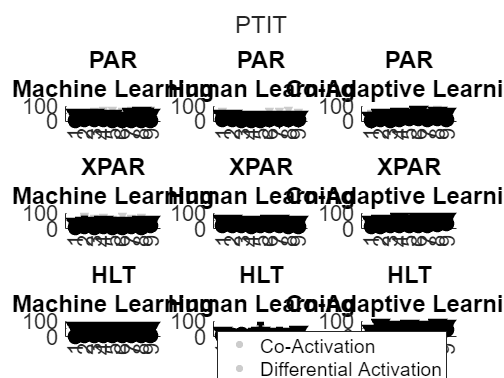

tlo = tiledlayout('flow');
fontsize(tlo, 20, "points")
ax_handle_list = [];
trials = (1:9)';
for cond = ["par", "xpar", "hlt"]
    y_cond = y_between(y_between.b_condition==cond,2:end);
    for task = ["Machine Learning", "Human Learning", "Co-Adaptive Learning"]
        y_coact = y_cond(:, and(y_within.w_task == task, y_within.w_gesture == "Co-Activation"));
        y_diffact = y_cond(:, and(y_within.w_task == task, y_within.w_gesture == "Differentiation"));
        y_coact_means = mean(y_coact);
        y_diffact_means = mean(y_diffact);
        y_coact_95ci = std(y_coact{:,:})./sqrt(size(y_coact, 1))*1.96;
        y_diffact_95ci = std(y_diffact{:,:})./sqrt(size(y_diffact, 1))*1.96;
        ax_handle = nexttile;
        ax_handle_list = [ax_handle_list, ax_handle];
        hold on
        scatter(trials, y_coact{:,:}', 50, 'black', 'filled', 'o', 'MarkerFaceAlpha', 0.20)
        scatter(trials, y_diffact{:,:}', 50, 'black', 'filled', 'v', 'MarkerFaceAlpha', 0.20)
        errorbar(trials, y_coact_means{:,:}, y_coact_95ci, '-ok', 'MarkerSize',10, 'MarkerFaceColor','black', 'LineWidth',3, 'MarkerEdgeColor','black')
        errorbar(trials, y_diffact_means{:,:}, y_diffact_95ci, ':vk', 'MarkerSize',10, 'MarkerFaceColor','black', 'LineWidth',3, 'MarkerEdgeColor','black')
        hold off
        title([upper(cond), task])
        xticks(1:9)
    end
end
legend(["Co-Activation", "Differential Activation"])
linkaxes(ax_handle_list, 'xy')
ylim([0, 100])
xlim([0 10])
title(tlo, upper(metric_type))
set(ax_handle_list, 'FontSize', 18)

rm = fitrm(y_between, 'y_1-y_54~b_condition', "WithinDesign",y_within)

rm =   RepeatedMeasuresModel with properties:

   Between Subjects:
         BetweenDesign: [12×55 table]
         ResponseNames: {1×54 cell}
    BetweenFactorNames: {'b_condition'}
          BetweenModel: '1 + b_condition'

   Within Subjects:
          WithinDesign: [54×3 table]
     WithinFactorNames: {'w_task'  'w_gesture'  'w_trial'}
           WithinModel: 'separatemeans'

   Estimates:
          Coefficients: [3×54 table]
            Covariance: [54×54 table]


ranova(rm, "WithinModel", "w_task + w_trial + w_gesture + w_trial*w_task")

ans = 15×8 table
                                  SumSq     DF    MeanSq        F         pValue       pValueGG      pValueHF      pValueLB 
                                  ______    __    _______    _______    __________    __________    __________    __________

    (Intercept)                    22309     1      22309       5471    7.6325e-14    7.6325e-14    7.6325e-14    7.6325e-14
    b_condition                   4.2416     2     2.1208    0.52009        0.6113        0.6113        0.6113        0.6113
    Error                         36.699     9     4.0777                                                                   
    (Intercept):w_task    

### Individual Data Plotter

task_label = "hl";
input_ttbl = participant_array(2).cond_dict("par").task_dict{task_label}.data_ttbl;
for t = 1:9
    trial_label = sprintf("Trial %02d", t)
    trial_ttbl = extract_segment(input_ttbl, trial_label, task_label);
    trmse_coact = compute_gesture_metric(trial_ttbl, "trmse", "Co-Activation");
    trmse_diffact = compute_gesture_metric(trial_ttbl, "trmse", "Differentiation");
    figure
    title(trial_label)
    subtitle(sprintf("Co-Activation:%.3f\t Differentiation:%.3f", trmse_coact, trmse_diffact))
    hold on
    plot(trial_ttbl.Time, trial_ttbl.("Targets"))
    plot(trial_ttbl.Time, trial_ttbl.("Kalman"))
    hold off
    box off
end

`compute_gesture_metric()`


% diffact_rows = segmented_ttbl.("Gesture") == "Differentiation";
% segmented_ttbl

`segment_data`

plot_bounds

function [fig_handle] = plot_bounded_fit(x, y, ax_handle, y_color)
y_fit = fit(x, y, 'poly1');
y_bounds = predint(y_fit, x, 0.95, 'functional', 'on');
x_conf = [x' flip(x')];
y_conf = [y_bounds(:,2)' flip(y_bounds(:,1)')];
hold on
rgb_color = convertStringsToChars(y_color);
rgb_color = reshape(sscanf(rgb_color(2:end), '%2x') / 255, [], 3);
p = fill(ax_handle, x_conf, y_conf, rgb_color);
p.FaceColor = [rgb_color];
p.FaceAlpha = 0.5;
p.EdgeColor = 'none';
plot(ax_handle, x, y_bounds, '--', 'Color',y_color); xlim ([0 10]); ylim([0 0.8]);
plot(ax_handle, x, [y, feval(y_fit, x)], 'Color', y_color);
hold off
end




Super loop